# ASE-4046 Exercise 3 Solutions

## Problem 1

One should always look at the data before fitting a curve!  

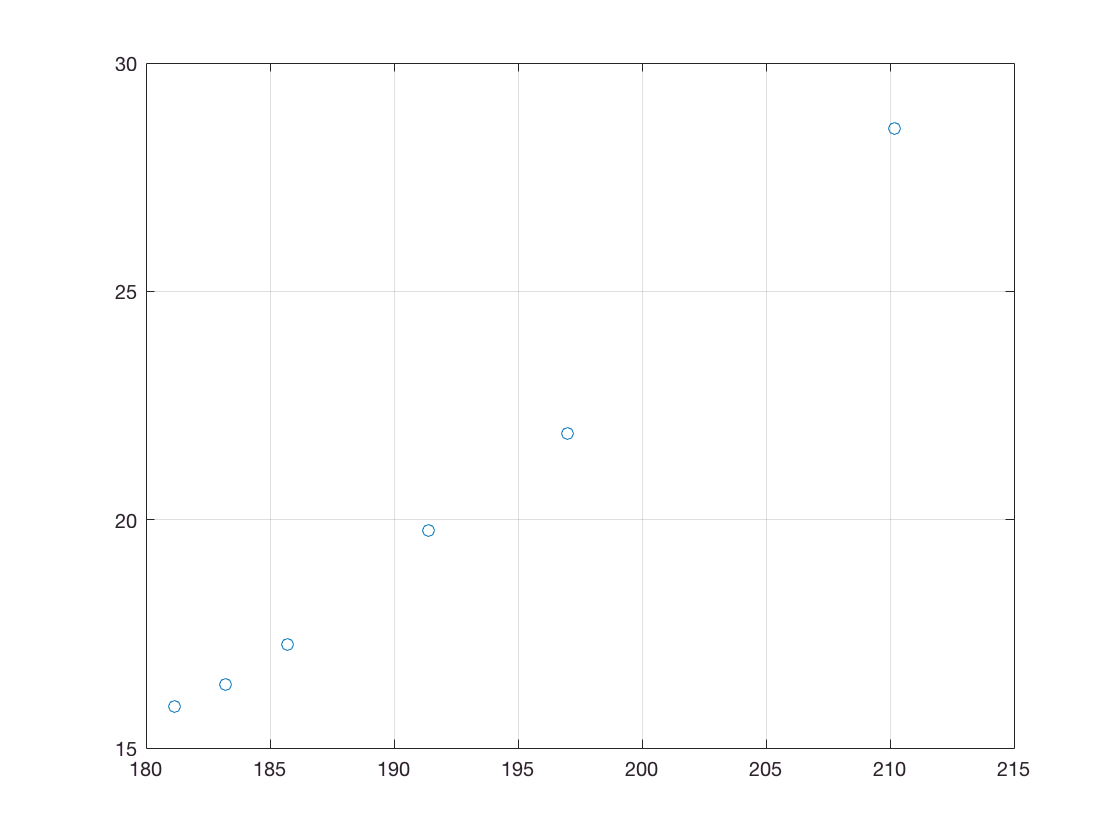

x=[210.2   197     191.4   185.7   183.2   181.15]'; % column vector
v=[28.559  21.892  19.758  17.267  16.385  15.919]';
plot(x,v,'o'); grid on

The points appear to lie on a slightly curved line, so an exponential fit seems reasonable. 

An exponential model can be fitted by fitting a straight line $y\approx b_1x+b_2$ to the log-transformed data. The formulas on slide 6 give the coefficients

y=log(v);
n=length(y); Sx=sum(x); Sx2=sum(x.^2); Sy=sum(y); Sxy=sum(x.*y);
b=[n*Sxy-Sx*Sy; Sx2*Sy-Sx*Sxy ]/(n*Sx2-Sx^2)

b =     0.0204
   -0.9309


 The same answer is obtained by solving the normal equation as on slide 15:

X=[x ones(n,1)]; 
bb=X\y

bb =     0.0204
   -0.9309


The fitted exponential model is  $v\approx \mathrm{e}^{b_1 x+b_2}=\mathrm{e}^{b_2}\mathrm{e}^{b_1 x}$, where

eb2=exp(b(2)), b1=b(1)

eb2 = 0.3942

b1 = 0.0204

 Plotting on semilog axes we see that the straight line is a good fit:

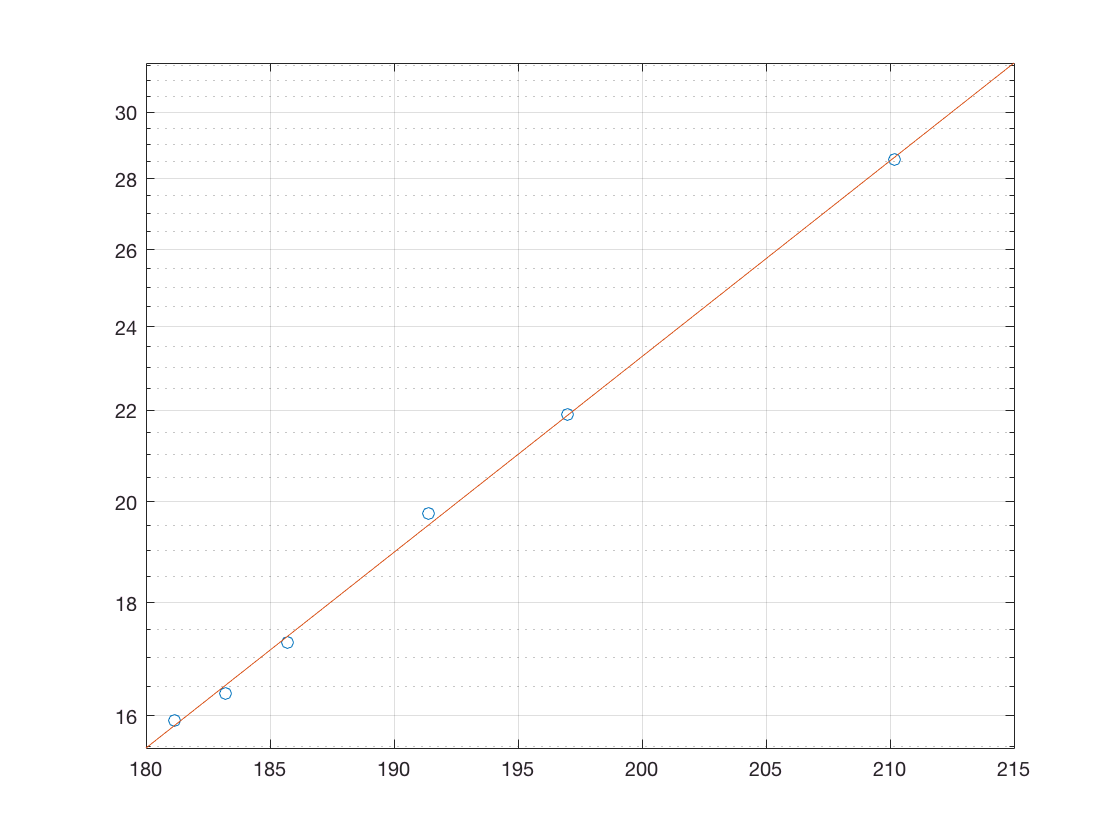

xx=180:215; 
yy=b(1)*xx+b(2); 
vv=exp(yy);
semilogy(x,v,'o',xx,vv); grid on

On linear axes we see that the fitted curve has some curvature:

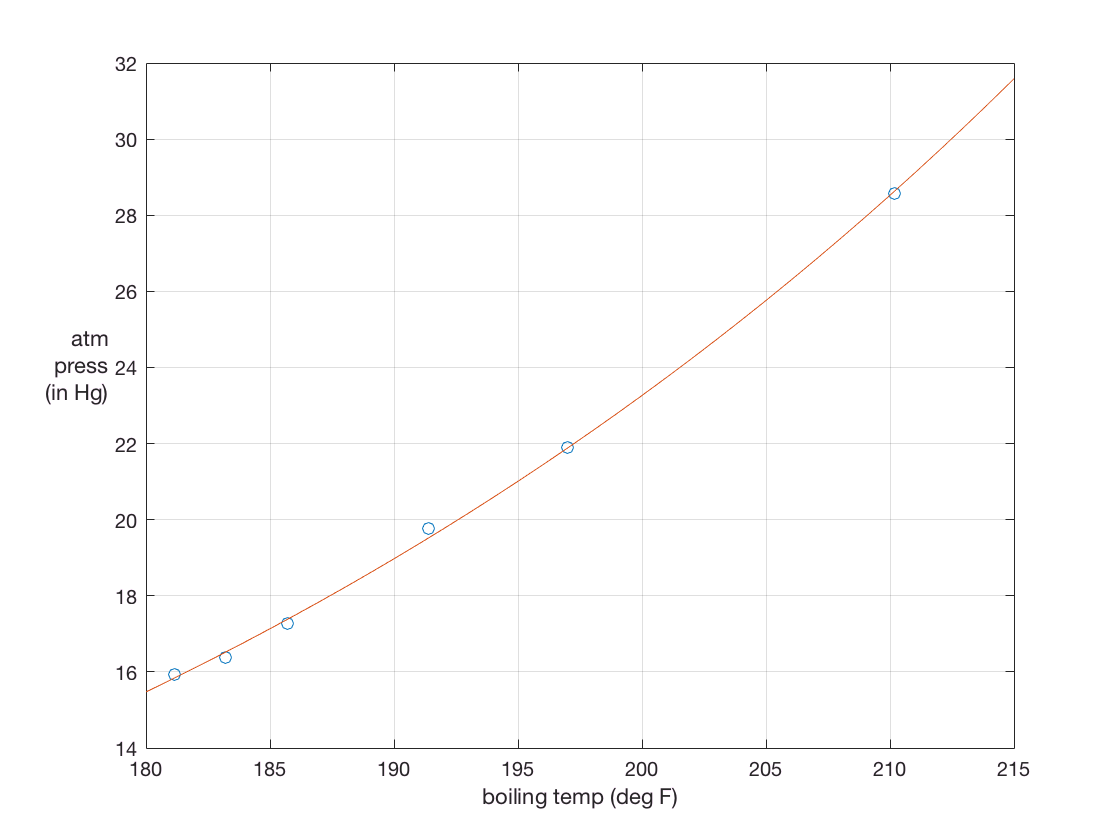

plot(x,v,'o',xx,vv); 
grid on 
xlabel('boiling temp (deg F)')
ylabel({'atm';'press';'(in Hg)'},'rot',0,'horiz','right')

## Problem 2

First, look at the data.   

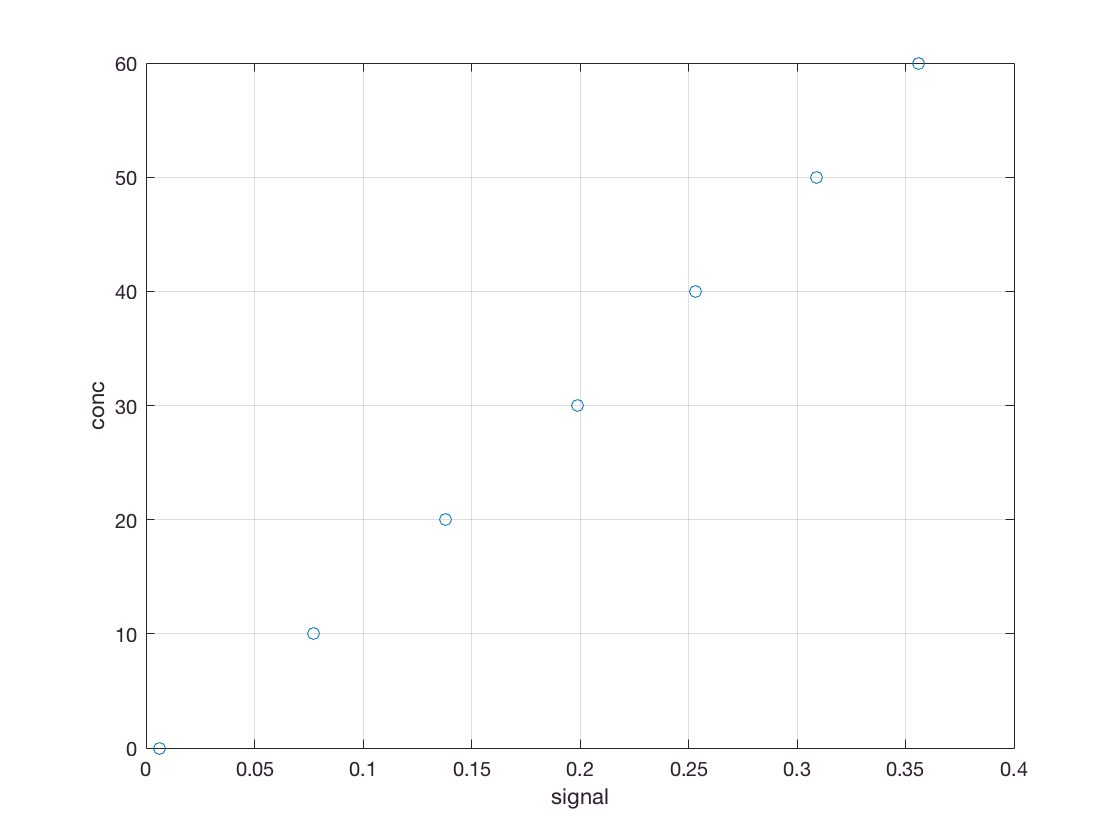

y=(0:10:60)'; % concentration, column vector
t=[0.006 0.077 0.138  0.199  0.253 0.309  0.356]'; % signal
plot(t,y,'o'); grid on; xlabel('signal'), ylabel('conc')

There appears to be a small amount of curvature. As instructed, we fit a degree 2 polynomial; this can be done by adapting the code on slide 16.

n=length(t);
tt=(2*t-t(1)-t(n))/(t(n)-t(1));  % transform to [-1,1]
d=2;  % polynomial degree
X=ones(n,d+1); for k=d:-1:1, X(:,k)=tt.*X(:,k+1); end % design matrix
bb=X\y;  % solve LS problem

The model predicts the following lead concentration of tap water at "your home" for the given instrument reading:

stap=0.278;   % instrument reading for your tap water
sstap=(2*stap-t(1)-t(n))/(t(n)-t(1)); % transform to [-1,1] scale
ctap=polyval(bb,sstap) % evaluate the polynomial

ctap = 44.4465

Plot the data and the curve. The lead concentration at "your home" is shown with a blue asterisk. 

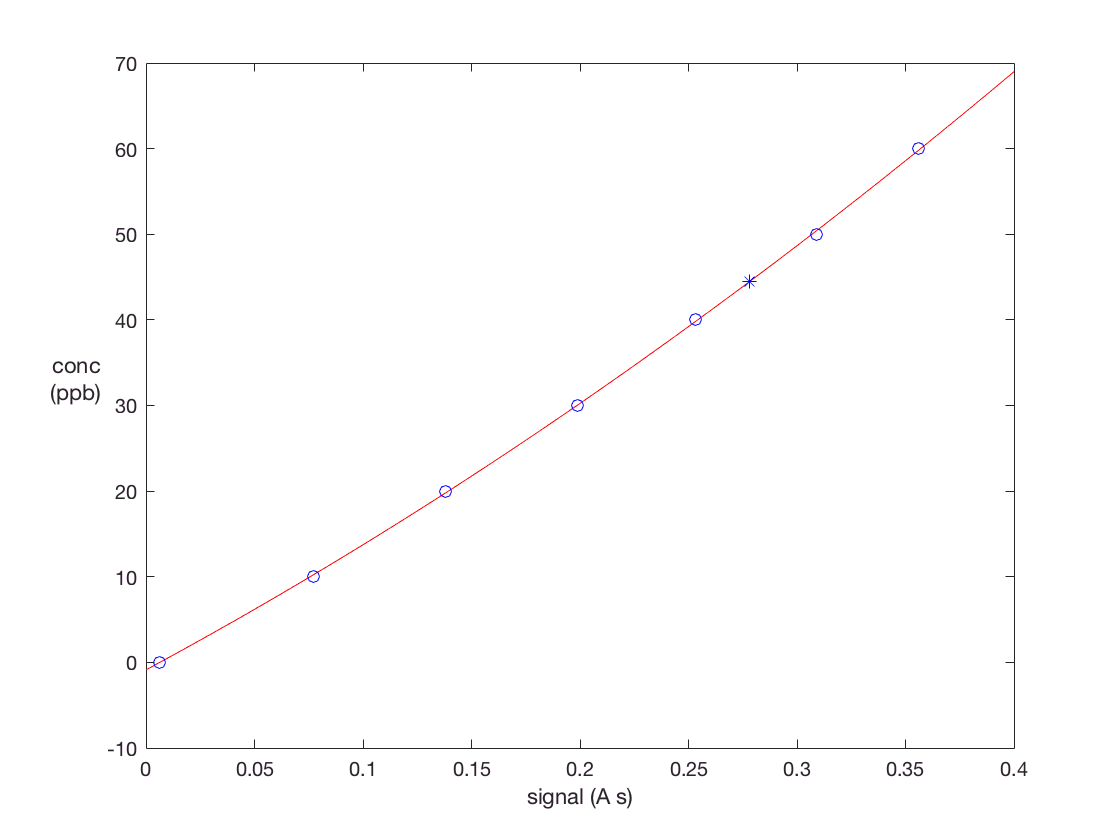

T=0:0.01:0.4;  %  mesh for plotting
TT=(2*T-t(1)-t(n))/(t(n)-t(1));   % transformed mesh
plot(T,polyval(bb,TT),'r-',t,y,'bo',stap,ctap,'b*')
xlabel('signal (A s)')
ylabel({'conc';'(ppb)'},'rot',0,'horiz','right')

**Problem 3**

First, we look at the data.  The outlier is clearly visible on the left. 

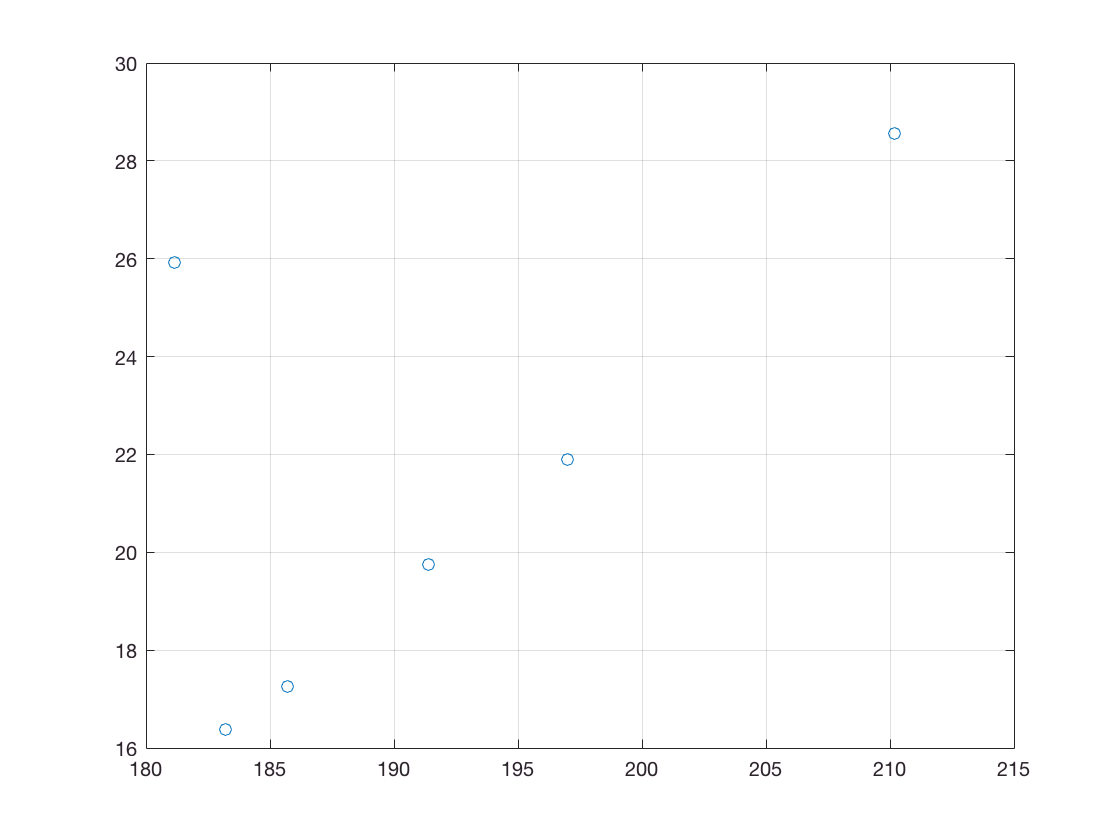

x=[210.2   197     191.4   185.7   183.2   181.15]';
v=[28.559  21.892  19.758  17.267  16.385  25.919]'; % with "typo"
plot(x,v,'o'); grid on

Here we fit a least-squares model to the log-transformed data: 

n=length(x);
y=log(v);
X=[x ones(n,1)]; 
bLS=X\y

bLS =     0.0119
    0.7794


Next we fit the least-absolute residuals model to the log-transformed data, as in slide 21.  For some versions of Matlab there is a warning message about the algorithm. 

f = [0 0 ones(1,2*n)]'; % cost = f' * [b; u; v] = sum(u) + sum(v) 
lb = [-inf -inf zeros(1,2*n)];  % constraints u >= 0, v >= 0
Aeq = [X eye(n) -eye(n)];  beq = y;  % constraint X*b + u - v = y
designvar = linprog(f,[ ],[ ],Aeq,beq,lb); % designvar = [ b; u; v] 

Optimization terminated.


bLAD = designvar(1:2);  % coefficients

The fitted exponential model is  $v\approx \mathrm{e}^{b_1 x+b_2}=\mathrm{e}^{b_2}\mathrm{e}^{b_1 x}$, where

eb2=exp(bLAD(2)), b1=bLAD(1)

eb2 = 0.4142

b1 = 0.0201

In the following plot we see that the LAD fit "ignores" the outlier and has a better fit to the remaining points. 

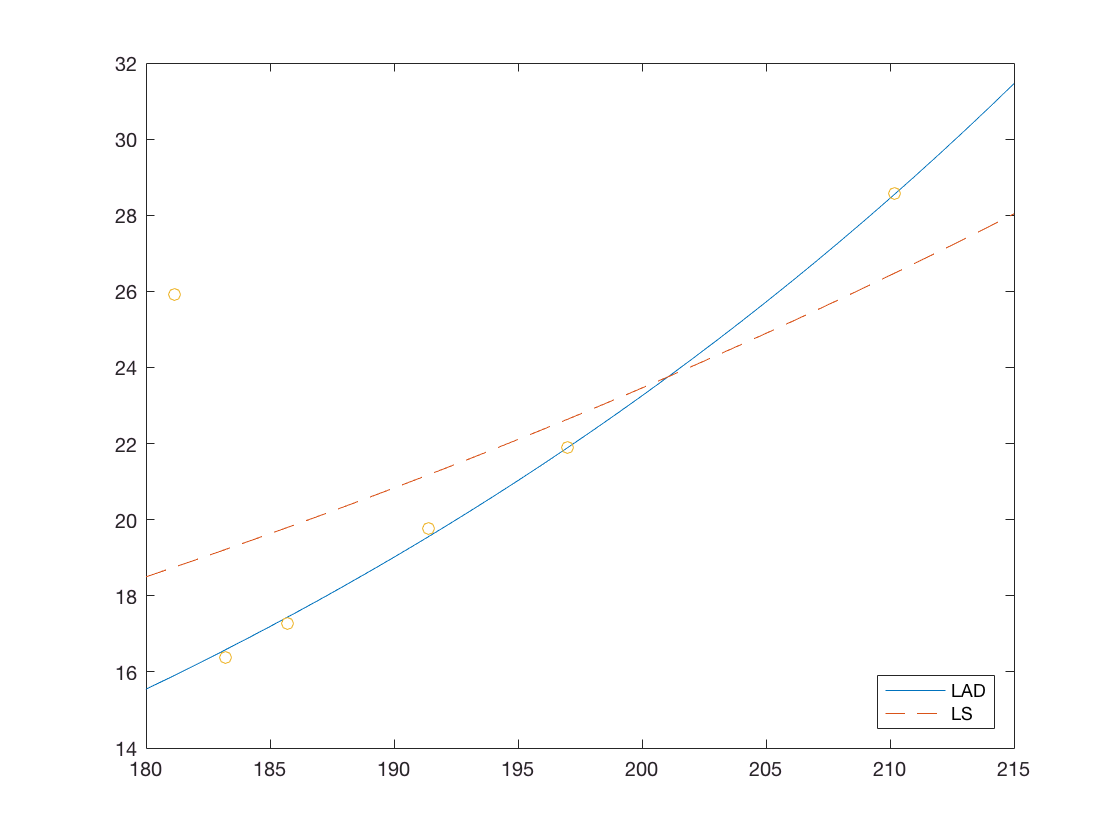

xx=180:215;   % dense mesh
yyLS=polyval(bLS,xx);
yyLAD=polyval(bLAD,xx);
plot(xx,exp(yyLAD),'-',xx,exp(yyLS),'--',x,v,'o')
legend('LAD','LS','location','southeast')